% Setup the workspace
% (Run once)

% this has a library to generate density scatterers (from Rehman)
addpath /data/tbrevett/Projects/DistributedAberrationCorrection/kWaveSoundSpeedSim4Thurston/standard_lib/

% this is a version of fullwave with associated functions (from Leah)
addpath /data/tbrevett/Programs/fullwave/fun/ % helper functions
copyfile /data/tbrevett/Programs/fullwave/bin/fullwave2_executable bin/ % executable

% kWave and kWaveArray should be added here


%#ok<*UNRCH> ignore unreachable code due to constant values
%#ok<*BDLGI> ignore casting numbers to logical values
device = -logical(gpuDeviceCount); % select 0 for cpu, -1 for gpu if you have one
% setup;  % add all the necessary paths
% setup parallel; % start a parpool for faster CPU processing
parpool('threads'); % start a limited but faster parpool - valid for R2021a+

Error using parpool
Found an interactive session. You cannot have multiple interactive sessions open simultaneously. To terminate the existing session, use delete(gcp('nocreate')).

setup CUDA cache;  % setup CUDA paths & recompile and cache local mex/CUDA binaries

% Setup the workspace
% (Run once)

% this has a library to generate density scatterers (from Rehman)
addpath /data/tbrevett/Projects/DistributedAberrationCorrection/kWaveSoundSpeedSim4Thurston/standard_lib/

% this is a version of fullwave with associated functions (from Leah)
addpath /data/tbrevett/Programs/fullwave/fun/ % helper functions
copyfile /data/tbrevett/Programs/fullwave/bin/fullwave2_executable bin/ % executable

% my version of kWave and kWaveArray - may have modifications 
addpath /data/tbrevett/Programs/MATLAB/k-Wave/
addpath /data/tbrevett/Programs/MATLAB/k-WaveArray/;


%#ok<*UNRCH> ignore unreachable code due to constant values
%#ok<*BDLGI> ignore casting numbers to logical values
device = -logical(gpuDeviceCount); % select 0 for cpu, -1 for gpu if you have one
% setup;  % add all the necessary paths
% setup parallel; % start a parpool for faster CPU processing
% if isempty(gcp()), parpool('threads'); end % start a limited but faster parpool - valid for R2021a+
% setup CUDA cache;  % setup CUDA paths & recompile and cache local mex/CUDA binaries
parpool('threads'); % start a limited but faster parpool - valid for R2021a+

Error using parpool
Found an interactive session. You cannot have multiple interactive sessions
open simultaneously. To terminate the existing session, use
delete(gcp('nocreate')).

setup CUDA cache;  % setup CUDA paths & recompile and cache local mex/CUDA binaries

## Create a simple simulation

Choose a transducer

xdc = TransducerArray.L11_5V(); % linear array
xdc.numel = 32;
% Choose the simulation region
% Make sure it covers the transducer!

% for Eikonal equation: grid sizing must be identically spaced
tscan = ScanCartesian(...
    'x', linspace(-20e-3, 20e-3, 1+40*2^3), ...
    'z', linspace( -4e-3, 56e-3, 1+60*2^3) ...
    );

% Choose an imaging region
scan = tscan; % use the same as the simulation region

% make a set of layer properties: sound speeds and depths
% yes, I know this is reversed ;)
[c0, z0] = deal(1500, 10e-3);
[c1, z1] = deal(1550, 20e-3);
[c2, z2] = deal(1600, 40e-3);
[c3, z3] = deal(3000,  +inf);
rho0 = 1020; % ambient density (kg/m^3)
imp0 = c0 * rho0; % ambient impedance

## Construct a medium

%opts_med = ["scatterer", "four_regions", "array", "diffuse"]; % medium options
%switch opts_med(2)
switch "four_regions"
    case 'scatterer'
        % Create a Medium with just a Point Scatterer

        % create a distributed medium based on the point scatterers
        % (this logic will later be implemented in a class)
        s_rad = max([tscan.dx, tscan.dz]); %, 260e-6); % scatterer radius
        ifun = @(p) vecnorm(p - [0;0;30e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat = {ifun, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties
        med = Medium('c0', c0, 'rho0', rho0, 'pertreg', {preg_scat});

    case 'four_regions'

        % Create a Medium from a series of constant regions

        % make the region functions: they must accept a point of size (3 x ...) and
        % return a logical of the same size.
        % the "sub" utility can index only certain dimensions at a time for us
        f1 = @(p) z0 <= sub(p,3,1) & sub(p,3,1) <= z1;
        f2 = @(p) z1 <= sub(p,3,1) & sub(p,3,1) <= z2;
        f3 = @(p) z2 <= sub(p,3,1) & sub(p,3,1) <= z3;

        % the impedance is the product of sound speed and density - make it
        % constant to avoid reflections from the interface
        % layer 0 - is the ambient layer: nothing to do
        preg1 = {f1, [c1, imp0 / c1]}; % layer 1
        preg2 = {f2, [c2, imp0 / c2]}; % layer 2
        preg3 = {f3, [c3, imp0 / c3]}; % layer 3
        preg_layered = {preg1, preg2, preg3};

        % add a point scatterer
        s_rad = max([tscan.dx, tscan.dz]); %, 260e-6); % scatterer radius
        ifun = @(p) vecnorm(p - [0;0;30e-3],2,1) < s_rad; % selection function: true if within the perturbation region
        preg_scat = {ifun, [c0, 2*rho0]}; % perturbation region - a pair with the select function and output properties

        % construct the medium
        med = Medium('c0', c0, 'rho0', rho0, 'pertreg', [preg_layered, {preg_scat}]);

    case "array"

        % Create a Medium from an array
        [Xg, ~, Zg] = tscan.getImagingGrid();
        C = c0*ones(tscan.size);  % ambient sound speed
        C(z0 <= Zg & Zg <= z1) = c1; % first region
        C(z1 <= Zg & Zg <= z2) = c2; % second region
        C(z2 <= Zg & Zg <= z3) = c3; % third region
        rho = rho0*ones(tscan.size); % density
        % get scatterer index (linear index)
        iscat = argmin(hypot(Xg - 0, Zg - 30e-3), [], 'all', 'linear'); 
        rho(iscat) = 2 *rho0; % make a single pixel density point scatterer

        med = Medium.Sampled(tscan, C, rho);

    case "diffuse"

        % Create a Medium with diffuse density scattering from an array
        [Xg, ~, Zg] = tscan.getImagingGrid();
        C = c0*ones(tscan.size);  % ambient sound speed
        C(z0 <= Zg & Zg <= z1) = c1; % first region
        C(z1 <= Zg & Zg <= z2) = c2; % second region
        C(z2 <= Zg & Zg <= z3) = c3; % third region

        % transmit signal properties
        omega0 = 2*pi*xdc.fc; % Center Radian Frequency of Transmitted Wave [rad/s]
        ncycles = max(1/xdc.bw_frac, seq.pulse.duration * xdc.fc); % Number of Cycles as Function of Bandwidth

        % Scatter Properties
        num_scat = 24;
        scat_size = 40e-6;
        scale = 5e-3; % Max Scat Variation from rho

        % create a scaterrer map (shamelessly stolen from Rehman's project)
        [rho_var, seedUsed] = scatfield(...
            num_scat, scat_size, scale, rho0, omega0, ...
            tscan.z(end), xdc.aperture_size, ncycles, ...
            tscan.dx, tscan.dz, numel(tscan.x), numel(tscan.z) ...
            ); % variation (X x Z)

        % create the isoimpedance density map
        del_rho = rho_var' - rho0; % variation - ambient
        rho_iso  = imp0 ./ C;         % isoimpedance
        rho_scat = rho_iso + del_rho; % scattering map


        % construct the medium(s)
        med(1) = Medium.Sampled(tscan, C, rho_iso);
        med(2) = Medium.Sampled(tscan, C, rho_scat);
end

% points per wavelength - aim for >2 for a simulation
ppw = c0/xdc.fc/min([tscan.dx, tscan.dz]);

## Choose the transmit sequence

if isa(xdc, 'TransducerArray')
    switch "FSA"
        case 'FSA', seq = Sequence('type', 'FSA', 'c0', c0, 'numPulse', xdc.numel); % set a Full Synthetic Aperture (FSA) sequence
        case 'Plane-wave',
            [amin, amax, Na] = deal( -25 ,  25 , 11 );
            seq = SequenceRadial('type', 'PW', ...
                'ranges', 1, 'angles',  linspace(amin, amax, Na), 'c0', c0); % Plane Wave (PW) sequence
        case 'Focused',
            [xmin, xmax, Nx] = deal( -10 ,  10 , 11 );
            seq = Sequence('type', 'VS', 'c0', c0, ...
                'focus', [1;0;0] .* 1e-3*linspace(xmin, xmax, Nx) + [0;0;30e-3] ... % translating aperture: depth of 30mm, lateral stride of 2mm
                ...'focus', [1;0;0] .* 1e-3*(-10 : 0.2 : 10) + [0;0;30e-3] ... % translating aperture: depth of 30mm, lateral stride of 0.2 mm
                );
    end
end

## Display the Medium

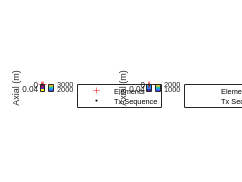

% Show the transducer's impulse response
% figure; plot(xdc.impulse, '.-'); title('Element Impulse Response');

% Show the transmit signal - a single point means it's a delta function
% figure; plot(seq.pulse, '.-'); title('Transmit signal');
%  Plot configuration of the simulation

figure; hold on; title('Geometry');
switch "both"
    case 'sound-speed', h = imagesc(med(1), tscan, 'c'         ); colorbar; % show the sound speed 
    case 'density',     h = imagesc(med(1), tscan, 'rho'       ); colorbar; % show the density
    case 'both',        h = imagesc(med(1), tscan, ["c", "rho"]); % show both
    arrayfun(@colorbar, [h.Parent]); % same as "colorbar(h(1).Parent); colorbar(h(2).Parent); ..."
    hold([h.Parent], 'on');
end
for ax = [h.Parent]
plot(xdc, ax, 'r+', 'DisplayName', 'Elements'); % elements
if scan.nPix < 500,
    hps = plot(scan, ax, 'w.', 'MarkerSize', 0.5, 'DisplayName', 'Image'); % the imaging points
else
    warning("Not displaying (" + scan.nPix + ") imaging points.");
end
switch seq.type % show the transmit sequence
    case 'PW', plot(seq, ax, 3e-2, 'k.', 'DisplayName', 'Tx Sequence'); % scale the vectors for the plot
    otherwise, plot(seq, ax, 'k.', 'DisplayName', 'Tx Sequence'); % plot focal points, if they exist
end
hl = legend(ax, 'Location','bestoutside');
set(ax, 'YDir', 'reverse'); % set transducer at the top of the image
end

## Simulate the Response

% Construct an UltrasoundSystem object, combining all of these properties,
% adn setting the sampling frequency of the output data
us = UltrasoundSystem('xdc', xdc, 'sequence', seq, 'scan', scan, 'fs', 40e6);

% Preferably, we use a parcluster to compute on - this makes it easy to
% send sims to the cluster
opts_clu = ["local", "Starling-GPU","Starling-CPU"];
switch opts_clu(2)
    case 'local', clu = parcluster('local'); % local computer - no setup required
        [clu.NumWorkers, clu.NumThreads] = deal(2, 4); % restrict to max 2 sims / 4 threads at a time
    case 'Starling-GPU',  clu = parcluster('Starling-GPU'); clu.SubmitArguments = clu.SubmitArguments + " --gpus=1"; % SLURM GPU partition
    case "Starling-CPU", clu = parcluster('Starling-CPU-bg'); % SLURM CPU background partition
end

% pick a folder for fullwave - it needs to write to disk
if clu.Profile == "local"
    fwsimdir = tempname(fullfile(pwd, 'sims')); % for fullwave, simulation in the working directory (current folder)
else
    user = strip(string(argn(2, @system, 'whoami'))); % get the username
    fwsimdir = tempname(fullfile('/data', user, 'fullwave', 'sims')); % make a temp directory for the simulation
end

% simulate the data
for i = numel(med):-1:1 % for each medium ...
    %switch "kWave"
    switch "kWave"
        case 'kWave', chd0(i) = kspaceFirstOrder(us, med(i), tscan, ...
                'CFL_max', 0.5, 'PML', [64 128], 'parcluster', clu, ... QUPS args
                'PlotSim', true ... KWave args - you can enter more here
                ); % giving a PML range selects an FFT friendly PML size

        case 'fullwave',
            conf = fullwaveConf(us, med(i), tscan, 'CFL_max', 0.3); % create a configuration structure
            job = us.fullwaveJob(conf, fwsimdir, clu); % create a job on the cluster
            submit(job); % launch - this may take a bit to copy over files
            wait(job); % wait for completion before reading back the data
        chd0(i) = us.readFullwaveSim(fwsimdir, conf); % create the ChannelData
    end
end

     1     1

    32    49    32

There are 154401 points in the grid which is 0.589 megabytes per grid variable.
FSA k-Wave simulation completed in 200.614 seconds.


## display the channel data across the transmits

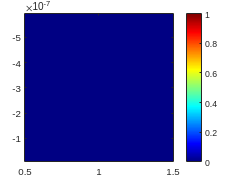

Error using caxis
Error setting property 'CLim' of class 'Axes':
Value must be a 1x2 vector of numeric type in which the second element is
greater than the first element or is Inf.


chd = mod2db(chd0); % == 20*log10(abs(x)) -> the power of the signl in decibels
figure; h = imagesc(chd, 1); colormap jet; colorbar; caxis(gather([-80 0] + (max(chd.data(chd.data < inf)))))

xlabel('Channel'); ylabel('Time (s)'); ylim([min(chd.time(:)), max(chd.time(:))]);
for m = 1:size(chd.data,3), if isvalid(h), h.CData(:) = chd.data(:,:,m); h.YData(:) = chd.time(:,:,min(m,size(chd.time,3))); drawnow limitrate; title(h.Parent, "Tx " + m); pause(1/10); end, end

## Create a B-mode Image

% Precondition the data
chd = chd0;
chd = singleT(chd); % use less data
chd.data = chd.data - mean(chd.data, 1, 'omitnan'); % remove DC

%chd.data = chd.data - nanmean(chd.data, 1); % remove DC

D = chd.getPassbandFilter(xdc.bw, 25); % get a 25-tap passband filter for the transducer bandwidth
chd = filter(chd, D); % apply passband filter for transducer bandwidth
if device, chd = gpuArray(chd); end % move data to GPU?
if isreal(chd), chd = hilbert(chd, 2^nextpow2(chd.T)); end % apply hilbert on real data

% Choose a beamforming method
apod = 1; % no apodization
%swith "DAS"
switch "Wavefield_Correlation"
    case "DAS"
        b =     bfDAS(us, chd, med(1).c0    , 'apod', apod, 'interp', 'cubic'); % use a vanilla delay-and-sum beamformer
    case "Eikonal"
        b = bfEikonal(us, chd, med(1), tscan, 'apod', apod, 'interp', 'cubic'); % use the eikonal equation for time delays
    case "DAS-direct"
        b =       DAS(us, chd, med(1).c0    , 'apod', apod, 'interp', 'cubic', 'device', device); % use a specialized delay-and-sum beamformer
    case "Wavefield_Correlation"
        % tscan.z should start at 0
        %assert(tscan.z(1) == 0, 'tscan.z should start at 0');
        % b = bfWavefieldCorrelation(us, chd, targ, tscan); % use
        b = bfWavefieldCorrelation(us, chd, med, tscan, 'interp', 'cubic'); % use

end

% show the image
b_im = mod2db(b); % convert to power in dB
figure; imagesc(scan, b_im(:,:,1), [-80, 0] + max(b_im(:))); % display with 80dB dynamic range
colormap gray; colorbar;
%}